
n = 10;
m = 1;
sigma = 0.01;
%iter = 100000;
num_run = 10;
h_M = [32 64 128 256 512 1024 2048 4096 8192];
norm_delta_w = zeros(2,length(h_M));
for k = 1:length(h_M)
h = h_M(k);
itanp = 10e-5;
wih_np = normrnd(0,1/sqrt(h),[h,n]);
who_np = normrnd(0,1/sqrt(h),[m,h]);
x = normrnd(0,1,[n,1]);
%fix target
rng('default');
rng(100);
w_star = rand(m,n);
y_tar = w_star*x;
initial_wih = wih_np;
initial_who = who_np;
etraj_in = norm(initial_who*initial_wih-w_star)^2;
%etraj = zeros(1,iter);
%thres = 0.98;
normalizede = 1;
iter = 0;
while normalizede>0.95 && iter<100000
% perturbation on hidden and output layers
enpo = normrnd(0,sigma,[m,1]);
enph = normrnd(0,sigma,[h,1]);
% without perturbation -> E
H = wih_np*x;
y = who_np*H;
e = 0.5*norm(y-y_tar)^2;
g_e = norm(who_np*wih_np-w_star)^2;
% with perturbation -> E_per
H_per = wih_np*x+enph;
y_per = who_np*H_per+enpo;
eper2 = 0.5*norm(y_per-y_tar)^2;
normalizede = g_e/etraj_in;
%disp(normalizede)
% weights update 
deltawho_np = -(itanp/sigma^2)*(eper2-e)*enpo*H';
deltawih_np = -(itanp/sigma^2)*(eper2-e)*enph*x';
%eb = (1-alpha)*eb+alpha*eper2;
wih_np = wih_np+deltawih_np;
who_np = who_np+ deltawho_np;
iter = iter+1;
end
norm_delta_wih = norm(wih_np-initial_wih)/norm(initial_wih);
norm_delta_w(1,k) = norm_delta_wih;
norm_delta_who = norm(who_np-initial_who)/norm(initial_who);
norm_delta_w(2,k) = norm_delta_who;
end

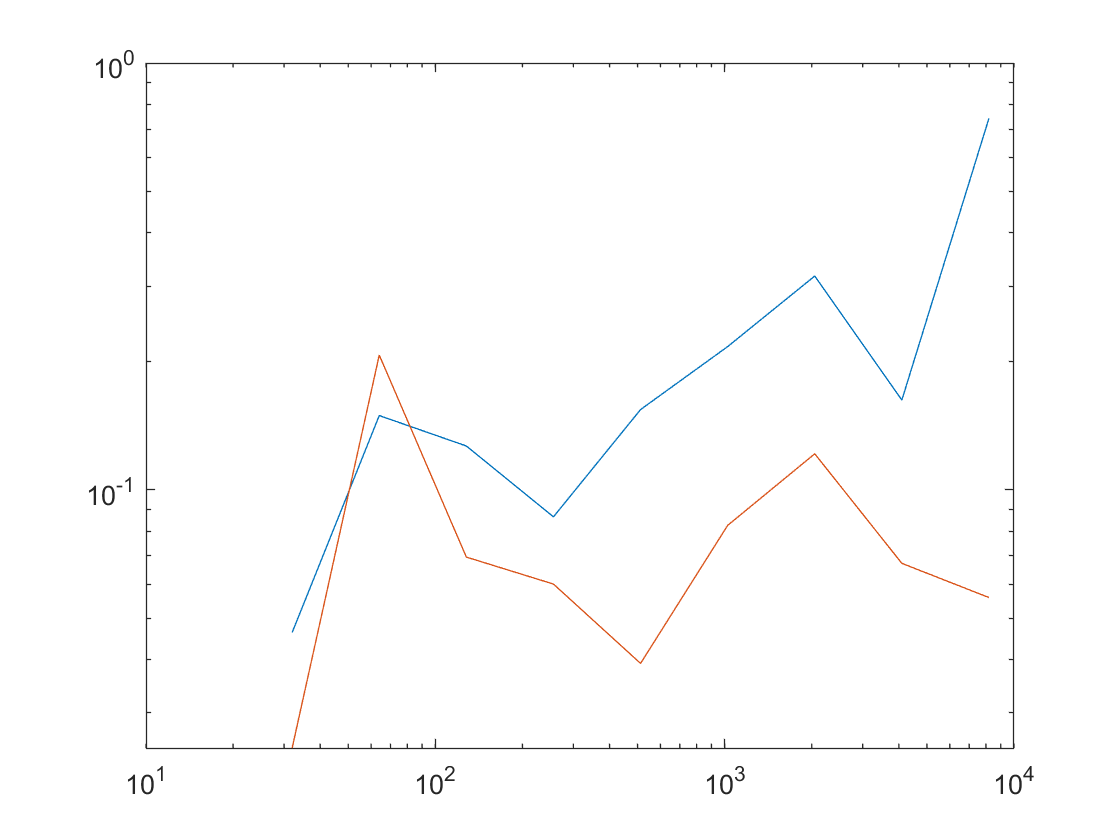

figure 
loglog(h_M, norm_delta_w(1,:));
hold on 
loglog(h_M, norm_delta_w(2,:));